%Pluto RX
SamplesPerFrame = 8000

SamplesPerFrame = 8000


nullIdx = []


nullIdx =

     []



numCarr = 1024;

cycprefix = numCarr/16;
modOrder = 4;  % for 4-QAM
bitsPerSymbol = log2(modOrder)

bitsPerSymbol = 2


GB_len = numCarr/16;
left_gb = 1:GB_len

left_gb =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


right_gb = (numCarr-GB_len+1):numCarr

right_gb =          961         962         963         964         965         966         967         968         969         970         971         972         973         974         975         976         977         978         979         980         981         982         983         984         985         986         987         988         989         990         991         992         993         994         995         996         997         998         999        1000        1001        1002        1003        1004        1005        1006        1007        1008        1009        1010


if mod(numCarr,2) == 0
    mid_guard = (numCarr/2)+1
else
    mid_guard = (numCarr+1)/2
end

mid_guard = 513


nullIdx = [left_gb, mid_guard, right_gb]'

nullIdx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


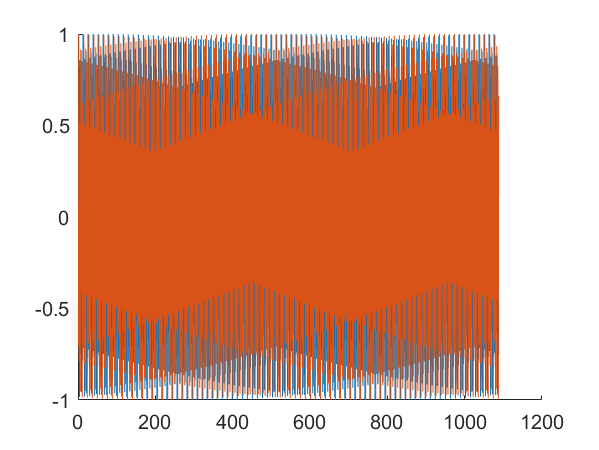


%raw_bits = textread('D:\Bristol\23-24\Project\Hardware\Simpler\Tx1\tx_bits.txt', '%d', 'delimiter', ' ')

read_header = load('D:\Bristol\23-24\Individual Project\20240410_2\Tx2\4QAM\complexArray.mat',"my_ofdm");
my_header = read_header.my_ofdm;
figure()
hold on;
plot(real(my_header))
plot(imag(my_header))
hold off;


temp = load('D:\Bristol\23-24\Individual Project\20240410_2\Tx2\4QAM\My_data.mat','My_data','pilot','pilotIdx','pilot_place')

temp = 包含以下字段的 struct :
        My_data: [1790×1 double]
          pilot: [64×1 double]
       pilotIdx: [32×1 double]
    pilot_place: [64×1 double]


My_data = temp.My_data

My_data =      0
     0
     1
     0
     0
     0
     1
     0
     1
     0


read_pilot = temp.pilot

read_pilot =      0
     0
     0
     0
     0
     1
     0
     1
     1
     1


read_pilot_place = temp.pilot_place

read_pilot_place =      1
     2
    57
    58
   113
   114
   169
   170
   225
   226


read_pilotIdx = temp.pilotIdx

read_pilotIdx =      1
    29
    57
    85
   113
   141
   169
   197
   225
   253



modulated_pilot = qammod(read_pilot,modOrder,"InputType","bit")

modulated_pilot =   -1.0000 + 1.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
   1.0000 - 1.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i
   1.0000 - 1.0000i



% read_tail = load('D:\Bristol\23-24\Project\Hardware\Simpler\Tx2\4QAM\my_tail.mat','my_tail');
% my_tail = read_tail.my_tail;


## Take care to set Gain to control the size of the Gain on the TX side. An overly large gain will create an overload and cause signal loss. 

my_gain = []


my_gain =

     []



my_differences = []


my_differences =

     []



my_percentage = []


my_percentage =

     []



for i = 0:5:70
my_gain = [my_gain;i];
rx = sdrrx('Pluto','CenterFrequency',915e+06,...
    'OutputDataType','double', ...
    'BasebandSampleRate',20e6,...
    'SamplesPerFrame',SamplesPerFrame,...
    'GainSource','manual','Gain',i);
%'GainSource','AGC Slow Attack'
%barker = [-1; -1; -1; 1; 1; -1; 1; 1];

%%

%信号接收
% for k=1:3
%     rx();
% end
Rx_Sig = rx();
%Rx_Sig = smoothdata(Rx_Sig,'gaussian',2);

% figure()
% hold on
% plot(real(Rx_Sig),'r')
% plot(imag(Rx_Sig),'b')
% hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% carrierSync = comm.CarrierSynchronizer(...
%     'DampingFactor', 6, ...
%     'NormalizedLoopBandwidth', 0.01, ...
%     'SamplesPerSymbol', 1, ... % 
%     'Modulation', 'QAM');
% [correctedSig, estCFO] = carrierSync(Rx_Sig)
% % Rx_Sig = correctedSig
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% save('test_receive.mat', 'Rx_Sig');

head_detec = comm.PreambleDetector('Input','Symbol','Preamble',my_header,'Threshold',2,'Detections','All');
[head_idx,head_detmet] = head_detec(Rx_Sig);
% [head_maxCorr, head_maxIndex] = max(head_detmet(1:length(Rx_Sig)-2*(numCarr+cycprefix)))
[head_maxCorr, head_maxIndex] = max(head_detmet(1:length(Rx_Sig)-2*(numCarr+cycprefix)));
% size(1:length(Rx_Sig)-4*(numCarr+cycprefix))

%Rx_data = Rx_Sig(maxIndex:maxIndex+136);

%%
from_head = head_maxIndex+1:head_maxIndex+(numCarr+cycprefix);
ofdm_received = Rx_Sig(from_head);

% figure()
% hold on
% plot(real(ofdm_received),'r')
% plot(imag(ofdm_received),'b')
% hold off

size_ofdm_received = size(ofdm_received);

% pilot_received = ofdm_received(read_pilotIdx);
data_received = ofdm_received;
% rxPilots = ofdmdemod(pilot_received,length(pilot_received),[],[],[])
my_received_data = ofdmdemod(data_received,numCarr,cycprefix,cycprefix,nullIdx);
rxPilots = my_received_data(read_pilotIdx);
estimatedChannelResponse = rxPilots ./ modulated_pilot;

carrIdx = 1:numCarr-length(nullIdx);
fullChannelEstimate = (interp1(read_pilotIdx, estimatedChannelResponse, carrIdx,  'linear', 'extrap'))';
fullChannelEstimate = conj(fullChannelEstimate);
equalizedSignal = my_received_data ./ fullChannelEstimate;

% scatterplot(equalizedSignal)

% % test pilot estimation
% pilot_estimation = rxPilots ./ estimatedChannelResponse
% test_pilot = qamdemod(pilot_estimation,modOrder,"OutputType","bit","UnitAveragePower",true)
% nnz(test_pilot~=My_Pilot_Bits)
% scatterplot(pilot_estimation)

% equalizedSignal = (my_received_data ./ estimatedChannelResponse)
% scatterplot(equalizedSignal)

qamDemodOut = qamdemod(equalizedSignal,modOrder,"OutputType","bit");

my_difference = nnz(My_data~=qamDemodOut);
percentage = my_difference/length(My_data);

% figure()
% temp = 20.*log10(abs(fullChannelEstimate));
% plot(temp)


differences = nnz(My_data ~= qamDemodOut);
percentage = differences/length(My_data);

my_differences = [my_differences;differences];
my_percentage = [my_percentage;percentage];

% find the error bits' place
indices = find(differences);

% figure()
% hold on
% plot(real(equalizedSignal),'r')
% plot(imag(equalizedSignal),'b')
% hold off
% 
% 
% figure()
% hold on
% plot(real(equalizedSignal),'r')
% plot(imag(equalizedSignal),'b')
% hold off
% 
% figure()
% hold on
% plot(real(qamDemodOut),'r')
% plot(imag(qamDemodOut),'b')
% hold off

end;

## Establishing connection to hardware. This process can take several seconds.
## Establishing connection to hardware. This process can take several seconds.
## Establishing connection to hardware. This process can take several seconds.
## Establishing connection to hardware. This process can take several seconds.
## Establishing connection to hardware. This process can take several seconds.
## Establishing connection to hardware. This process can take several seconds.
## Establishing connection to hardware. This process can take several seconds.
## Establishing connection to hardware. This process can take several seconds.
## Establishing connection to hardware. This process can take several seconds.
## Establishing connection to hardware. This process can take several seconds.
## Establishing connection to hardware. This process can take several seconds.
## Establishing connection to hardware. This process can take several seconds.
## Establishing connection to hardware. This process

my_gain

my_gain =      0
     5
    10
    15
    20
    25
    30
    35
    40
    45


my_differences

my_differences =    241
   153
    56
    26
    13
     0
     1
     1
     1
     1


my_percentage

my_percentage =     0.1346
    0.0855
    0.0313
    0.0145
    0.0073
         0
    0.0006
    0.0006
    0.0006
    0.0006


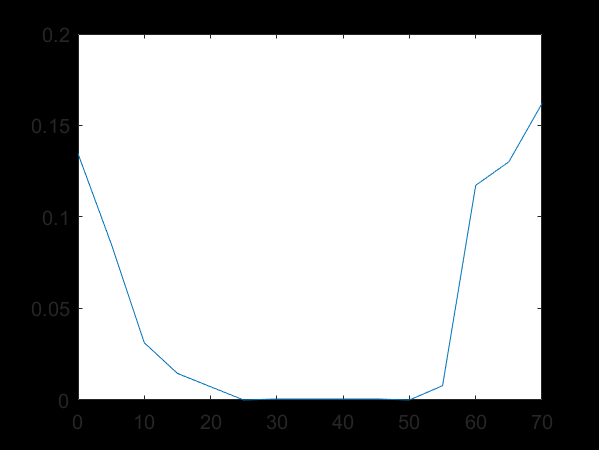

figure()
plot(my_gain,my_percentage)